## Find Amplitude and $\phi \;$of Sinusoidal wave

We know that $\textrm{Asin}\;\left(\omega t+\phi \right)=c_{1\;} \sin \;\omega t+c_2 \cos \;\omega t$. when $A=\sqrt{c_1^2 +c_2^2 }$ and $\;\phi =\arctan \left(\frac{c_2 }{c_1 }\right)\ldotp \;$

In the first dection, we generate sine wave $5\sin \;\left(100t+2\right)+N\left(t\right)$. when $N\left(t\right)\;$is a noise.

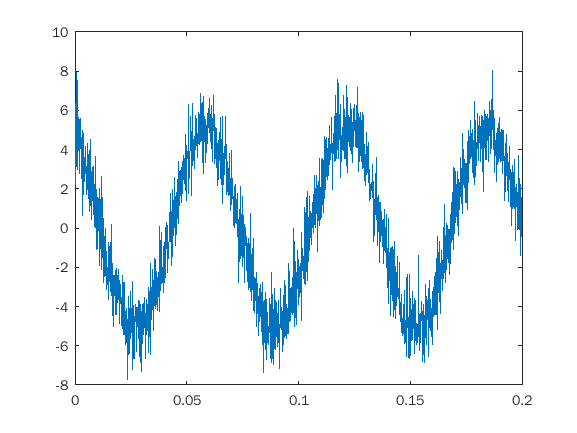

clc; clear;

w = 100;
t = [0:1e-4:0.2];
y = 5*sin(w*t + 2) + randn(1,length(t));
plot(t,y)

From above data, we can write $c_1 ,c_2$ and $y$ in form $\textrm{Gx}=b$ which is

                                  
$$\left\lbrack \begin{array}{cc}
\sin \;\omega t_1  & \cos \;\omega \;t_{1\;} \\
\sin \;\omega t_1  & \cos \;\omega \;t_{1\;} \\
\sin \;\omega t_1  & \cos \;\omega \;t_{1\;} \\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
\sin \;\omega t_1  & \cos \;\omega \;t_{1\;} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
c_1 \\
c_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
y_3 \\
\ldotp \ldotp \ldotp \\
y_n 
\end{array}\right\rbrack$$
 

Using psuedo-inverse matrix to find $c_{1\;}$and $c_2$.

G = [sin(w*t)' cos(w*t)'];
c = G\y'; %equal to inv(G'G)*G'
Amp = sqrt(c'*c)

Amp = 5.0822

phi = atan2(c(2),c(1))

phi = 2.0068

y_fit = Amp*sin(w*t+phi);

plot(t,y,'g',t,y_fit,'--r')
xlabel('Time (s)'); ylabel('Amplitude'); title('Sinusoidal wave');
legend('Actual response', 'Estimated response')

Simulation Part

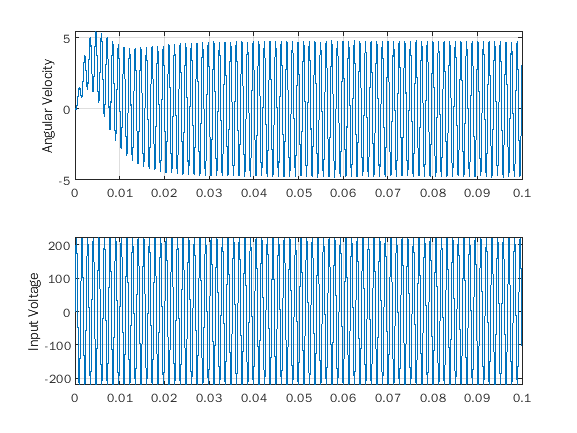

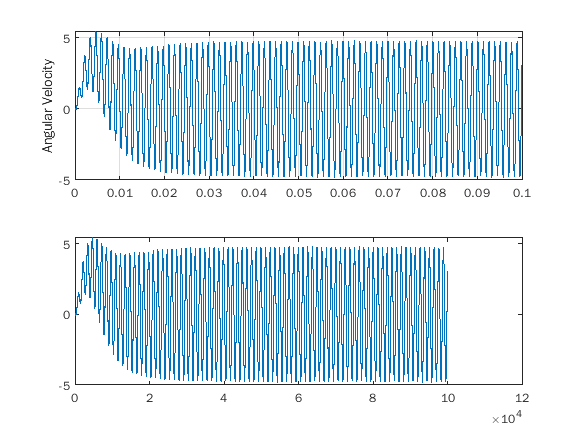

clc; clear; warning off;
W = 5000; %rad/sec

tstop = 0.1;
simout = sim('Lab_Identification.slx', 'StopTime', num2str(tstop),'FixedStep','1e-6');
y = simout.velocity;
u = simout.voltage;
t = simout.tout;

subplot(2,1,1)
plot(t,y); grid on;
ylabel('Angular Velocity'); %xlim([0 length(t)]);
subplot(2,1,2)
plot(t,u); grid on;
ylabel('Input Voltage'); %xlim([0 length(t)

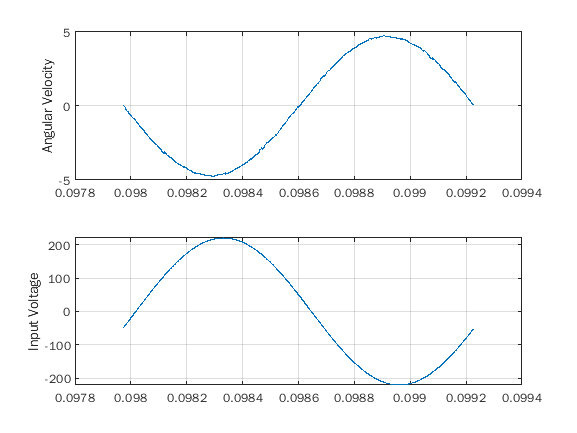

figure
Tstart = 97975; Tstop = 99229;
subplot(2,1,1)
plot(t(Tstart:Tstop),y(Tstart:Tstop)); grid on;
ylabel('Angular Velocity'); %xlim([0 length(t)]);
subplot(2,1,2)
plot(t(Tstart:Tstop),u(Tstart:Tstop)); grid on;
ylabel('Input Voltage'); %xlim([0 length(t)])

% output = velocity
A = [sin(W*t(Tstart:Tstop)) cos(W*t(Tstart:Tstop))];
b = A\y(Tstart:Tstop);
phiy = atan2(b(2),b(1))*(180/pi)

phiy = -167.4106


b1 = A\u(Tstart:Tstop);
phiu = atan2(b1(2),b1(1))*(180/pi)

phiu = -0.0022


phi = phiy - phiu

phi = -167.4085

clc; clear;
W = 10;

simout = sim('Lab_Identification.slx','StartTime','0', 'StopTime', '3','FixedStep','1e-5');
y = simout.velocity;
u = simout.input;
t = simout.tout;

A = [sin(W*t) cos(W*t)];
b = A\u;
phiu = atan2(b(2),b(1))*(180/pi);

c = A\y; %equal to inv(A'A)*A'
Amp1 = sqrt(c'*c)/220

Amp1 = 1.7429

phi1 = atan2(c(2),c(1))*(180/pi) - phiu

phi1 = -2.0177

W = 20;

simout = sim('Lab_Identification.slx','StartTime','0', 'StopTime', '2','FixedStep','1e-5');
y = simout.velocity;
u = simout.input;
t = simout.tout;

A = [sin(W*t) cos(W*t)];
b = A\u;
phiu = atan2(b(2),b(1))*(180/pi);

c = A\y; %equal to inv(A'A)*A'
Amp2 = sqrt(c'*c)/220

Amp2 = 1.7411

phi2 = atan2(c(2),c(1))*(180/pi) - phiu

phi2 = -4.0408

W = 50;

simout = sim('Lab_Identification.slx','StartTime','0', 'StopTime', '1','FixedStep','1e-5');
y = simout.velocity;
u = simout.input;
t = simout.tout;

A = [sin(W*t) cos(W*t)];
b = A\u;
phiu = atan2(b(2),b(1))*(180/pi);

c = A\y; %equal to inv(A'A)*A'
Amp3 = sqrt(c'*c)/220

Amp3 = 1.7284

phi3 = atan2(c(2),c(1))*(180/pi) - phiu

phi3 = -10.1009

W = 100;

simout = sim('Lab_Identification.slx','StartTime','0.1', 'StopTime', '1','FixedStep','1e-5');
y = simout.velocity;
u = simout.input;
t = simout.tout;

A = [sin(W*t) cos(W*t)];
b = A\u;
phiu = atan2(b(2),b(1))*(180/pi);

c = A\y; %equal to inv(A'A)*A'
Amp4 = sqrt(c'*c)/220

Amp4 = 1.6812

phi4 = atan2(c(2),c(1))*(180/pi) - phiu

phi4 = -20.2479

W = 200;

simout = sim('Lab_Identification.slx','StartTime','0.5', 'StopTime', '1','FixedStep','1e-6');

Program interruption (Ctrl-C) has been detected.

y = simout.velocity;
u = simout.input;
t = simout.tout;

A = [sin(W*t) cos(W*t)];
b = A\u;
phiu = atan2(b(2),b(1))*(180/pi);

c = A\y; %equal to inv(A'A)*A'
Amp5 = sqrt(c'*c)/220
phi5 = atan2(c(2),c(1))*(180/pi) - phiu
W = 500;

simout = sim('Lab_Identification.slx','StartTime','0.2', 'StopTime', '0.5','FixedStep','1e-6');
y = simout.velocity;
u = simout.input;
t = simout.tout;

A = [sin(W*t) cos(W*t)];
b = A\u;
phiu = atan2(b(2),b(1))*(180/pi);

c = A\y; %equal to inv(A'A)*A'
Amp6 = sqrt(c'*c)/220
phi6 = atan2(c(2),c(1))*(180/pi) - phiu
W = 1000;

simout = sim('Lab_Identification.slx','StartTime','0.1', 'StopTime', '0.4','FixedStep','1e-7');
y = simout.velocity;
u = simout.input;
t = simout.tout;

A = [sin(W*t) cos(W*t)];
b = A\u;
phiu = atan2(b(2),b(1))*(180/pi);

c = A\y; %equal to inv(A'A)*A'
Amp7 = sqrt(c'*c)/220
phi7 = atan2(c(2),c(1))*(180/pi) - phiu
W = 2000;

simout = sim('Lab_Identification.slx','StartTime','0.1', 'StopTime', '0.3','FixedStep','1e-7');
y = simout.velocity;
u = simout.input;
t = simout.tout;

A = [sin(W*t) cos(W*t)];
b = A\u;
phiu = atan2(b(2),b(1))*(180/pi);

c = A\y; %equal to inv(A'A)*A'
Amp8 = sqrt(c'*c)/220
phi8 = atan2(c(2),c(1))*(180/pi) - phiu
W = 5000;

simout = sim('Lab_Identification.slx','StartTime','0.04', 'StopTime', '0.1','FixedStep','1e-7');
y = simout.velocity;
u = simout.input;
t = simout.tout;

A = [sin(W*t) cos(W*t)];
b = A\u;
phiu = atan2(b(2),b(1))*(180/pi);

c = A\y; %equal to inv(A'A)*A'
Amp9 = sqrt(c'*c)/220
phi9 = atan2(c(2),c(1))*(180/pi) - phiu
W = 10000;

simout = sim('Lab_Identification.slx','StartTime','0.04', 'StopTime', '0.08','FixedStep','1e-8');
y = simout.velocity;
u = simout.input;
t = simout.tout;

A = [sin(W*t) cos(W*t)];
b = A\u;
phiu = atan2(b(2),b(1))*(180/pi);

c = A\y; %equal to inv(A'A)*A'
Amp10 = sqrt(c'*c)/220
phi10 = atan2(c(2),c(1))*(180/pi) - phiu
W = 20000;

simout = sim('Lab_Identification.slx','StartTime','0.04', 'StopTime', '0.08','FixedStep','1e-8');
y = simout.velocity;
u = simout.input;
t = simout.tout;

A = [sin(W*t) cos(W*t)];
b = A\u;
phiu = atan2(b(2),b(1))*(180/pi);

c = A\y; %equal to inv(A'A)*A'
Amp11 = sqrt(c'*c)/220
phi11 = atan2(c(2),c(1))*(180/pi) - phiu
%Amp = 20*log([1.7418 1.7411 1.7284 1.6704 1.5401 0.9359 0.3858 0.1112 0.0164 0.0044 0.0011]);
%deg = [-2.0177 -4.0408 -10.1009 -19.7799 -39.0412 -83.0517 -122.0207 -148.8568 -167.0644 -173.4139 -176.5001];
Amp = 20*log([Amp1 Amp2 Amp3 Amp4 Amp5 Amp6 Amp7 Amp8 Amp9 Amp10 Amp11]);
deg = [phi1 phi2 phi3 phi4 phi5 phi6 phi7 phi8 phi9 phi10 phi11];
w = [10 20 50 100 200 500 1000 2000 5000 10000 20000];

figure
subplot(2,1,1)
semilogx(w,Amp)
xlabel('\omega (rad/sec)'); ylabel('Amplitude (dB)')
subplot(2,1,2)
semilogx(w,deg)
xlabel('\omega (rad/sec)'); ylabel('Phase (Deg)');

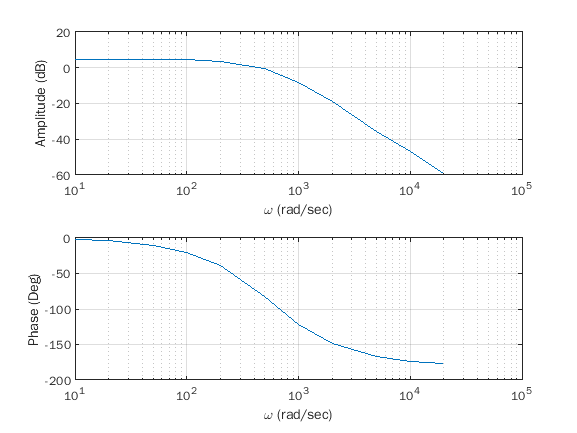

Amp = 20*log10([1.7418 1.7411 1.7284 1.6704 1.5401 0.9359 0.3858 0.1112 0.0164 0.0044 0.0011]);
deg = [-2.0177 -4.0408 -10.1009 -19.7799 -39.0412 -83.0517 -122.0207 -148.8568 -167.0644 -173.4139 -176.5001];
w = [10 20 50 100 200 500 1000 2000 5000 10000 20000];
figure
subplot(2,1,1)
semilogx(w,Amp)
xlabel('\omega (rad/sec)'); ylabel('Amplitude (dB)')
ylim([-60,20])
yticks(-60:20:20);
grid on
subplot(2,1,2)
semilogx(w,deg)
xlabel('\omega (rad/sec)'); ylabel('Phase (Deg)');
grid on

s = tf('s');
sys = 1.7418/(((s/663.907)+1)*((s/450)+1))
[mag,phase,wout] = bode(sys,{10,20000});
mag = squeeze(mag);
phase = squeeze(phase);

figure
subplot(2,1,1)
semilogx(w,Amp,'b',wout,20*log10(mag),'r');
xlabel('\omega (rad/sec)'); ylabel('Amplitude (dB)')
legend('Actual data','Estimated data')
ylim([-150,20])
yticks(-160:20:20);
grid on
subplot(2,1,2)
semilogx(w,deg,'b',wout,phase,'r')
xlabel('\omega (rad/sec)'); ylabel('Phase (Deg)');